	 	 **Practical Problems 1 – Basic Commands** 	

In MATLAB, create vectors **x** = (1,2,3,4,5) and **y** = (1,2,3,4,5) using any two different methods.	 	

x = [1, 2, 3, 4, 5]

x =      1     2     3     4     5


y = [1, 2, 3, 4, 5]

y =      1     2     3     4     5


Add the two vectors together and examine the output.	 

x + y

ans =      2     4     6     8    10


Sum the elements of the answer to question 2.	 	 	

sum(x + y)

ans = 30

Add the 3rd element of `x` to the last element of `y`, and assign the output to the variable `z`.	 	 	

z = x(3) + y(end)

z = 8

Replace the 4th element of `x` with 7.	 	 	

x(4) = 7

x =      1     2     3     7     5


Extend the vector `y` with the value 6 so that it has 6 elements.

y(end + 1) = 6

y =      1     2     3     4     5     6


Shorten the vector `y` by assigning the empty matrix to element 3.	 	 

y(3) = []

y =      1     2     4     5     6


Create three column vectors of length 3 named `c1`,` c2`, and `c3`. Create a 3x3 matrix called `A` using these column vectors.	 	 	

c1 = [1, 2, 3]'

c1 =      1
     2
     3


c2 = [4, 5, 6]'

c2 =      4
     5
     6


c3 = [7, 8, 9]'

c3 =      7
     8
     9


A = [c1, c2, c3]

A =      1     4     7
     2     5     8
     3     6     9


Calculate the determinant of the matrix `B`**.**	

B = [1, 2, 3 ; 4, 5, 6 ; 7, 8, 9]

B =      1     2     3
     4     5     6
     7     8     9


det(B)

ans = 6.6613e-16

Calculate the eigenvalues of the matrix `B`**.**

eig(B)

ans =    16.1168
   -1.1168
   -0.0000


Create a row vector,and a column vector,	 	 	

a = [3, 6, 9], b = [3 ; 6 ; 9]

a =      3     6     9


b =      3
     6
     9


Perform matrix and then element-wise multiplication on these two vectors. Can you explain the error in the second case if your Matlab version is before 2017, or can you explain what is happening in later versions of Matlab?	 

a * b

ans = 126

a .* b

ans =      9    18    27
    18    36    54
    27    54    81


Transpose the vector `a` and create a 3x2 matrix called **myMat** using it with `b`.	 

myMath = cat(2, transpose(a), b)

myMath =      3     3
     6     6
     9     9


Add the second element on the first row to the first element of the second row.	 	 	

myMath(2, 1) + myMath(1, 2)

ans = 9

Create a random 2x2 array of non-integers and give it a name.	 

random = rand(2, 2)

random =     0.9572    0.8003
    0.4854    0.1419


Round the array to the nearest integer.	 	 	

round(random)

ans =      1     1
     0     0


Find the number of elements in the array.	 	 	

numel(random)

ans = 4

Find its maximum and minimum values.

max(random, [], 'all')

ans = 0.9572

min(random, [], 'all')

ans = 0.1419

Find the maximum value on the 2nd row using a single command.	 	 

max(random(:, 2))

ans = 0.8003

Create a random vector of non-integers of length 8 and give it a name.	 	 

random2 = rand(1, 8)

random2 =     0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340


Sort the vector into ascending order.	 	 	

sort(random2)

ans =     0.0357    0.4218    0.6557    0.7922    0.8491    0.9157    0.9340    0.9595


Round the 2nd, 4th, 6th and 8th elements **up** to the nearest integer, and the 1st, 3rd, 5th and 7th elements **down** to the nearest integer.	 	 		 	 

random2([2, 4, 6, 8]) = ceil(random2([2, 4, 6, 8]))

random2 =     0.4218    1.0000    0.7922    1.0000    0.6557    1.0000    0.8491    1.0000


random2([1, 3, 5, 7]) = floor(random2([1, 3, 5, 7]))

random2 =      0     1     0     1     0     1     0     1


Generate a random 9x9 matrix of integers called `C`.

C = randi([-10, 10], 9, 9)

C =      4   -10     6     4     5    -5     2     5     1
     5    -8     6     3    -5     7    -1    -3    -1
     5     7    -7    -7     0    -5    -3     1   -10
    -2     4     0    -8     4     7     7    -9    -3
     3    -4    -1     0     8    -5     2    -9    -7
    -7     9     3    10    10     9     1     1     6
     4   -10     4    -3     1    -3     9     6    -4
   -10    -1     5     2    -8    -6    -4     9     1
    -5    -2    -5    -6    -7    -5     5    -8    -7


Add the 4th column of `C` to the 6th column.	 	 	

column_sum = C(:, 4) + C(:, 6)

column_sum =     -1
    10
   -12
    -1
    -5
    19
    -6
    -4
   -11


Create a 3x3 matrix `D` from the top left minor of matrix `C`, and a matrix `E` from the bottom right minor of matrix `C`.	 	 	

D = C(1:3, 1:3)

D =      4   -10     6
     5    -8     6
     5     7    -7


E = C(7:9, 7:9)

E =      9     6    -4
    -4     9     1
     5    -8    -7


Perform the element-wise multiplication `DE` and `ED`.	 	 	

DE = D .* E

DE =     36   -60   -24
   -20   -72     6
    25   -56    49


ED = E .* D

ED =     36   -60   -24
   -20   -72     6
    25   -56    49


Perform the matrix multiplication `DE` and `ED`.

D * E

ans =    106  -114   -68
   107   -90   -70
   -18   149    36


E * D

ans =     46  -166   118
    34   -25    23
   -55   -35    31


Create two character arrays of the same length (number of letters) called s1 and s1.	

s1 = 'Hello'

s1 = 'Hello'

s2 = 'World'

s2 = 'World'

Create a new character array s3 by concatenating s1 with s2.	 

s3 = [s1, s2]

s3 = 'HelloWorld'

Sort the character array s3 into alphabetical order.	 	 	

sort(s3)

ans = 'HWdellloor'

Create a vector `x`` = (1,2,3,4,5,6,7,8)`.	 	 	

x = 1:8

x =      1     2     3     4     5     6     7     8


Create a vector `y`` = 2``x`.	 	 	

y = 2 * x

y =      2     4     6     8    10    12    14    16


Plot `y` against `x`.	 	 	

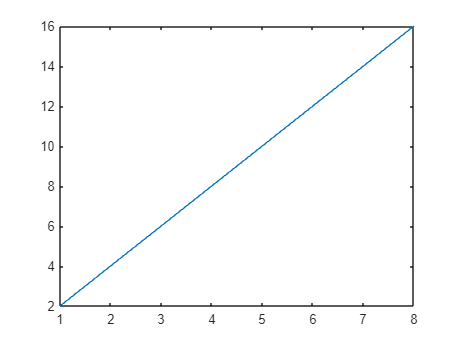

plot(x, y)

Create a vector of 100 points from 0 to `π `called *x*.	 	 	

x = linspace(0, pi, 100)

x =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203    0.9520    0.9837    1.0155    1.0472    1.0789    1.1107    1.1424    1.1741    1.2059    1.2376    1.2693    1.3011    1.3328    1.3645    1.3963    1.4280    1.4597    1.4915    1.5232    1.5549


Plot `y`` = sin(``x``)`.	 	 	

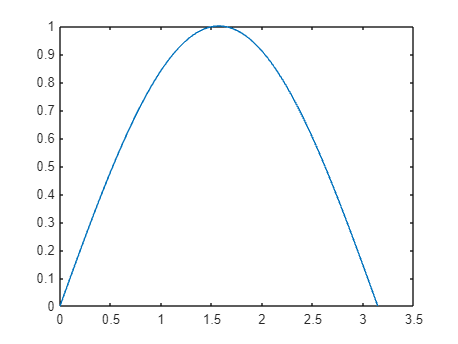

plot(x, sin(x))

Find out in the documentation how to change the line colour and style.

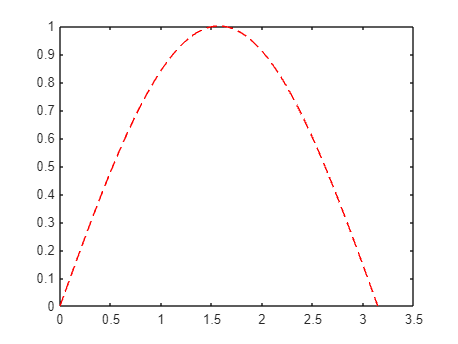

plot(x, sin(x), 'r--');